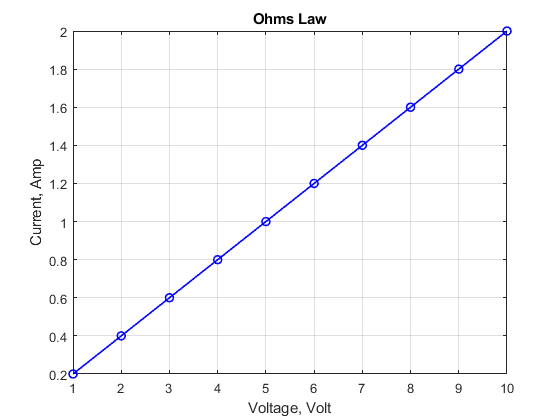

% Ohm's Law: V=IR
% Voltage, V=[1:10]
% Resistance, R=5 ohms
% Plot voltage vs current
V=1:10; R=5;
I=V/R;
plot(V,I,'o-b','Linewidth',1.2);
xlabel('Voltage, Volt');
ylabel('Current, Amp');
title('Ohms Law');
grid on;

% Equivalent resistance
% R1 + (R2||R3)
R1=10; R2=5; R3=4;
Equivalent_R= R1 + ((R2*R3)/(R2+R3));
fprintf('Equivalent resistance: %f',Equivalent_R)

Equivalent resistance: 12.222222

% Delta to wye conversion
% Delta configured resistances:
% Rd1=10 ohms, Rd2= 5 ohms, Rd3= 20 ohms
% Equivaelent wye configured resistances:
% Ry1, Ry2, Ry3
clc;clear;
Rd1=10; Rd2=5; Rd3=20;
Ry1= (Rd1*Rd2)/(Rd1+Rd2+Rd3);
Ry2= (Rd1*Rd3)/(Rd1+Rd2+Rd3);
Ry3= (Rd2*Rd3)/(Rd1+Rd2+Rd3);
fprintf('Equivalent wye configured resistances:\n');

Equivalent wye configured resistances:


fprintf('Ry1= %f   Ry2= %f    Ry3= %f\n',Ry1,Ry2,Ry3);

Ry1= 1.428571   Ry2= 5.714286    Ry3= 2.857143


% Wye to delta conversion
% Delta configured resistances:
% Ry1=10 ohms, Ry2= 5 ohms, Ry3= 20 ohms
% Equivaelent wye configured resistances:
% Rd1, Rd2, Rd3
clc;clear;
Ry1=10; Ry2=5; Ry3=20;
Rd1= (Ry1*Ry2+Ry2*Ry3+Ry3*Ry1)/Ry3;
Rd2= (Ry1*Ry2+Ry2*Ry3+Ry3*Ry1)/Ry2;
Rd3= (Ry1*Ry2+Ry2*Ry3+Ry3*Ry1)/Ry1;
fprintf('Equivalent delta configured resistances:\n');

Equivalent delta configured resistances:


fprintf('Rd1= %.3f   Rd2= %.3f    Rd3= %.3f\n',Rd1,Rd2,Rd3);

Rd1= 17.500   Rd2= 70.000    Rd3= 35.000


% Equivalent resistance with Delta-wye conversion
% R1, R2, R3: Delta configuration
% First step: Conversion into wye configuration
% Hence,find Ry1, Ry2, Ry2
% Second step: Find Rs1 and Rs2
% Third step: Find Rp
% Fourth step: Find overall equivalent resistance, Req
clc;clear;
R1=2; R2=4; R3=6; R4=3; R5=2;
Ry1= (R1*R2)/(R1+R2+R3);
Ry2= (R1*R3)/(R1+R2+R3);
Ry3= (R2*R3)/(R1+R2+R3);
Rs1= Ry2+R4;
Rs2= Ry3+R5;
Rp= (Rs1*Rs2)/(Rs1+Rs2);
Req= Ry1+Rp;
fprintf('The equivalent resistance: %.3f ohms\n',Req);

The equivalent resistance: 2.667 ohms


% Circuit problem
% R1= 2 ohms; R2=R3= 4 ohms
% Voltage source, E =10 V
% Determine loop current IL1 and IL2
% Determine current, I1, I2, and I3
% Determine voltage across resistance R3: VR3
% Determine voltage across resistance R2: VR2
% Determine voltage across resistance R1: VR1
clc;clear;
R1=2; R2=4; R3=4;
syms IL1 IL2
eqn1= 6*IL1-4*IL2==10;
eqn2= -4*IL1+8*IL2==0;
[IL1,IL2]=solve(eqn1,eqn2);
fprintf('The ABCD loop current, IL1: %.3f A\n',IL1);

The ABCD loop current, IL1: 2.500 A


fprintf('The BEFC loop current, IL2: %.3f A\n',IL2);

The BEFC loop current, IL2: 1.250 A



I1=IL1; I2=IL2;
I3= I1-I2;

fprintf('The currents in the circuit:\n');

The currents in the circuit:


fprintf('I1= %.3f A  I2= %.3f A  I3= %.3f A\n',I1,I2,I3);

I1= 2.500 A  I2= 1.250 A  I3= 1.250 A



VR1=I1*R1;
VR2=I3*R2;
VR3=I2*R3;

fprintf('The voltage across R1, VR1= %.3f V\n',VR1);

The voltage across R1, VR1= 5.000 V


fprintf('The voltage across R2, VR2= %.3f V\n',VR2);

The voltage across R2, VR2= 5.000 V


fprintf('The voltage across R3, VR3= %.3f V\n',VR3);

The voltage across R3, VR3= 5.000 V


% Voltage divider
% R1= 2 ohms; R2= 4 ohms; R3=8 ohms; E= 24 V
% Determine the voltage across the resistances R2 and R3
clc;clear;
R1=2; R2=4; R3=8; E=24;
VR2=(R2/(R1+R2+R3))*E;
VR3=(R3/(R1+R2+R3))*E;
fprintf('Voltage across the resistance R2: %.3f V\n',VR2);

Voltage across the resistance R2: 6.857 V


fprintf('Voltage across the resistance R3: %.3f V\n',VR3);

Voltage across the resistance R3: 13.714 V


% Current divider
% R1= 2 ohms; R2= 4 ohms; I= 16 A
% Determine the current through the resistances R1 and R2
clc;clear;
R1=2; R2=4; I=16;
I1=(R2/(R1+R2))*I;
I2=(R1/(R1+R2))*I;
fprintf('Current through the resistance R1, I1: %.3f A\n',I1);

Current through the resistance R1, I1: 10.667 A


fprintf('Current through the resistance R2, I2: %.3f A\n',I2);

Current through the resistance R2, I2: 5.333 A


% Thevenin's theorem
% R1= 4 ohms; R2= 2 ohms; R3= 3 ohms; RL= 5 ohms; V= 10 V;
% Determine: Thevenin's voltage, Vth
% Determine: Thevenin's equivalent resistance, Rth
% Determine: Load current, IRL
clc;clear;
R1=4; R2=2; R3=3; RL=5; V=10;
Vth= ((R2)/(R1+R2))*V;
Rth= ((R1*R2)/(R1+R2))+R3;
fprintf('Thevenin voltage: %.3f V\n',Vth);

Thevenin voltage: 3.333 V


fprintf('Thevenin equivalent resistance: %.3f ohms\n',Rth);

Thevenin equivalent resistance: 4.333 ohms


IRL=Vth/(Rth+RL);
fprintf('Load current: %.3f A\n',IRL);

Load current: 0.357 A


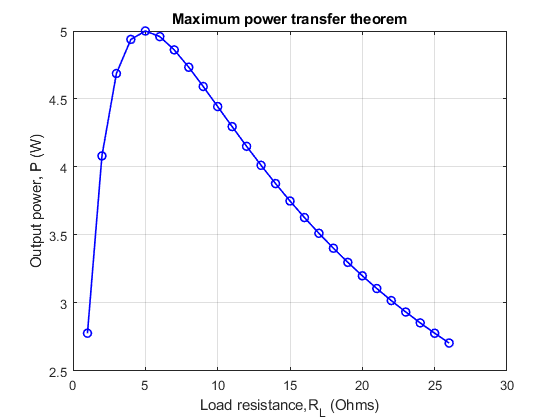

% Maximum power transfer theorem
% Rth= 5 ohms; Vth= 10 V
clc;clear;
Rth=5; Vth=10;
RL= 1:1:26;
for i=1:1:26
    I(i)=Vth/(Rth+RL(i));
    Power(i)=I(i)^2*RL(i);
end
plot(RL,Power,'o-b','LineWidth',1.2);
xlabel('Load resistance,R_L (Ohms)');
ylabel('Output power, P (W)');
title('Maximum power transfer theorem');
grid on;

% Maximum power, when RL=Rth
RL=5;
P_max=(Vth/(Rth+RL))^2*RL;
fprintf('Maximum output power= %.3f\n',P_max);

Maximum output power= 5.000


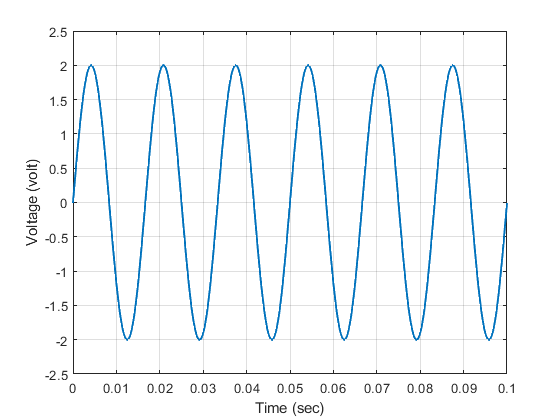

% v(t)=10 sin(2*pi*f*t)
% f= 60 Hz; t= 0:0.1 sec
% Determine: Peak voltage, Vp
% Determine: Peak to peak voltage, Vpp
% Determine: RMS voltage, V_rms
% Determine: Average voltage, V_avg
% Determine: Instantaneous voltage at T=0.02 sec, v_inst
clc;clear;
f = 60;
t = 0:0.0001:0.1;
v = 2*sin(2*pi*f*t);
plot(t,v,'LineWidth',1.5);
xlabel('Time (sec)');
ylabel('Voltage (volt)');
ylim([-2.5 2.5]);
grid on;

Vp=max(abs(v));
fprintf('Peak voltage: %.3f\n',Vp);

Peak voltage: 2.000


Vpp=2*Vp;
fprintf('Peak to peak voltage: %.3f\n',Vpp);

Peak to peak voltage: 4.000


V_rms=(1/sqrt(2))*Vp;
fprintf('RMS voltage: %.3f\n',V_rms);

RMS voltage: 1.414


V_avg=(2/pi)*Vp;
fprintf('Average voltage: %.3f\n',V_avg);

Average voltage: 1.273


T=0.02;
V_inst=2*sin(2*pi*f*T);
fprintf('Instantaneous voltage at T=0.02 sec: %.3f\n',V_inst);

Instantaneous voltage at T=0.02 sec: 1.902


% Impedance
% R= 10 ohms; L= 0.02 H; C= 0.05 F; f= 60 Hz
% Determine Impendance: Z
% Power facor: PF
clc;clear;
R=10; L=0.02; C=0.05;
f=60;
XL=2*pi*f*L;
XC=1/(2*pi*f*C);
disp('Impedance:')

Impedance:


Z=R+j*(XL-XC)

Z = 10.0000 + 7.4868i

Imp_magnitude=abs(Z);
Phase_angle=angle(Z)*(180/pi);
disp('In polar form:');

In polar form:


fprintf('|Z|= %.3f ohms;  Phase angle= %.3f degree\n',...
    Imp_magnitude,Phase_angle);

|Z|= 12.492 ohms;  Phase angle= 36.821 degree


PF=cos(Phase_angle);
fprintf('Power factor= %.3f\n',PF);

Power factor= 0.639


% Power traingle
% P= 10 W, Q=5 Var
% Find: Apparent power, S
% Find Power factor, PF
clc;clear;
P=10; Q=5;
disp('Apparent power:')

Apparent power:


S=P+j*Q

S = 10.0000 + 5.0000i

S_mag=abs(S);
S_angle=angle(S)*(180/pi);
fprintf('Apparent power in polar form:\n');

Apparent power in polar form:


fprintf('|S|= %.3f VA    Power angle= %.3f degree\n',S_mag,S_angle);

|S|= 11.180 VA    Power angle= 26.565 degree


PF=cos(S_angle);
fprintf('Power factor= %.3f\n',PF);

Power factor= 0.138


% Inverting amplifier
% Input voltage: V_in=40 V;
% Resistances: R1=4 Ohms; R2=2 Ohms;
% Find: Gain, G
% Find: Output voltage, V_out
clc; clear;
V_in=40; R1=4; R2=2;
G=-(R2/R1);
V_out=G*V_in;
fprintf('Gain: %.2f\n',G);

Gain: -0.50


fprintf('Output voltage: %.2f\n',V_out);

Output voltage: -20.00


% Transistor problem
% Common base connection
% Emitter current, I_E= 10 mA; Alpha=0.8
% Determine: Collector current, I_C;
% Determine: Base current, I_B;
clc;clear;
I_E=10; Alpha=0.8;
I_C=Alpha*I_E;
I_B= I_E-I_C;
fprintf('Collector current: %.3f mA\n',I_C);
fprintf('Base current: %.3f mA\n',I_B);